# 6.1. Программирование в MATLAB

**Лекция**

## Операторы проверки

В MATLAB существует целый класс функций, целью которых явяляется проверка соответствия/несоответствия входной переменной определённому типу данных. 

Например, функция `isnumeric` проверяет аргумент на то, является ли он численной переменной или нет:

isnumeric('Вася')

ans = logical
   0


isnumeric(1991)

ans = logical
   1


В предыдущих разделах рассматривались функции `isnan` и `isfinite`**. **

Следует рассмотреть особую функцию - `iskeyword`. Она проверяет, является ли входная комбинация символов зарезервированной MATLAB служебной комбинацией:

iskeyword('break')

ans = logical
   1


Общий список зарезервированных MATLAB слов:

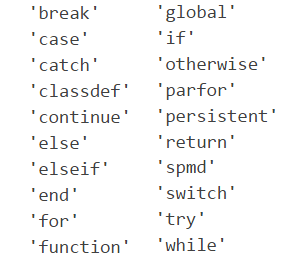

## Условные операторы

Возможности MATLAB позволяют выполнять условные инструкции, обеспечивающие выполнение определённой команды (набора команд) только при условии истинности некоторого логического выражения, либо выполнение одной из нескольких команд (наборов команд) в зависимости от значения некоторого выражения.

Первая конструкция основана `if-elseif-else`, а её синтаксис в MATLAB имеет вид: 

        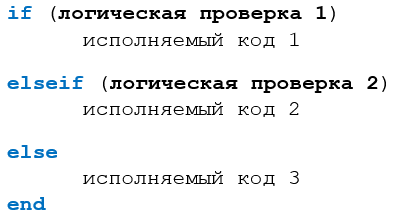

Пример:

x1 = 4;
if (x1 == 3)        % условие не выполняется, вложенный код не исполняется
    x2 = 1;     
elseif (x1 > 3)     % условие выполняется, вложенный код исполняется
    x2 = 2;
else                
    x2 = 3;
end
x2

x2 = 2

Еще одним условным конструктом является `switch-case`. Её синтаксис имеет вид:

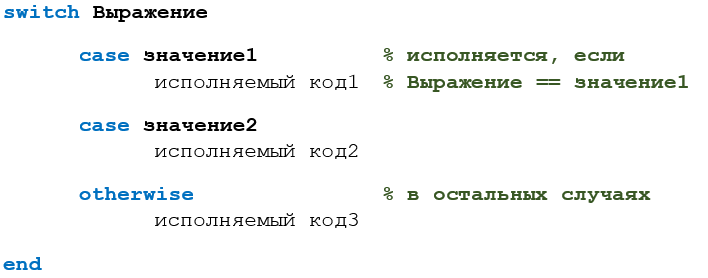

Пример:

x1 = 'New York'

x1 = 'New York'

switch x1
    case 'New York'
        disp('Hello New York');
    case 'Moscow' 
        disp('Привет Москва')
    otherwise
        x2 = 3;
end

Hello New York


x2

x2 = 2

## Циклы в MATLAB

Циклы повторяют блок кода в рамках более крупной программы. Цикл `for` выполняет код фиксированное число раз. Каждый раз, проходя цикл, параметр цикла (или индекс цикла) принимает указанное значение. Индекс цикла является переменной MATLAB и может использоваться в теле цикла. 

Синтаксис цикла `for` имеет вид: 

Можно заметить, что для работы цикла `for` создается вектор-строка, а `Индекс` последовательно проходит от первого значения вектора до последнего. Вместо создания вектора-строки можно использовать уже имеющийся вектор:

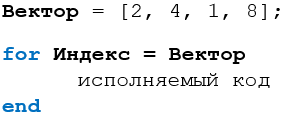

Пример:

log_sum = 0;
for i = 3:1:6
    log_sum = log_sum + log(i)
end

log_sum = 1.0986

log_sum = 2.4849

log_sum = 4.0943

log_sum = 5.8861

sin_sum = 0;
for i = [ pi/6, 5*pi/6, pi/2, -pi/2 ]
    sin_sum = sin_sum + sin(i)
end

sin_sum = 0.5000

sin_sum = 1.0000

sin_sum = 2

sin_sum = 1

В случае, если количество итераций цикла неизвестно, может быть использован второй вариант описания цикла: конструкция `while-end`. `Исполняемый код` выполняется до тех пор, пока выполняется `Условие`: 

Пример:

x1 = 2; i = 0;
while x1 < 10000
    x1 = x1 + x1^2
    i = i + 1
end

x1 = 6

i = 1

x1 = 42

i = 2

x1 = 1806

i = 3

x1 = 3263442

i = 4

%[a, i]

Остерегайтесь бесконечных циклов! 

В случае, если при выполнении кода в теле цикла требуется прекратить работу цикла, то для этого используется команда `break`, а если требуется прекратить текущую итерацию, но продолжить работу цикла, то для этого используют команду `continue`:

for i = 1:1:100
    if(i==3)
        continue
    elseif (i==7)
        break
    end
    i
end

i = 1

i = 2

i = 4

i = 5

i = 6

Зачастую бывает полезно знать размеры матриц и векторов (например для использования этих размеров при определении циклов). Для этого используются функции `size`, `length` и `numel`. Функция `size` выдаёт строку, содержащую размеры матрицы (кол-во строк и столбцов), функция `length` определяет наибольшую из этих величин и как правило используется по отношению к векторам, а функция `numel` выдаёт общее количество компонент матрицы:

 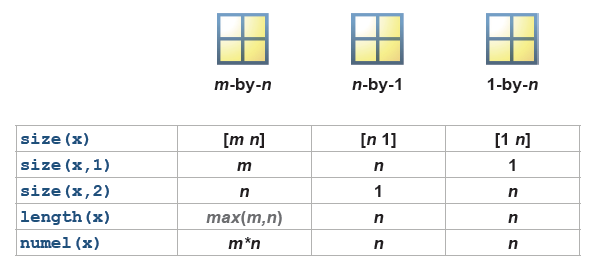

## Ввод и вывод данных

MATLAB предлагает несколько функций для работы с пользователем в процессе выполнения программы. Пользователь может вводить данные как в командном окне, так и во всплывающих окнах. 

Перечень функций представлен в таблице:

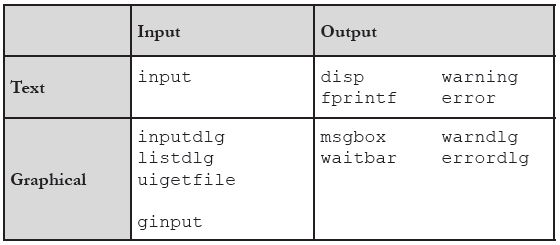

Пример вывода: 

disp(32)

    32



warning("Предупреждение")

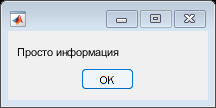

msgbox("Просто информация")

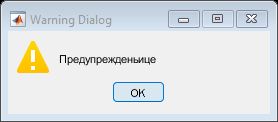

warndlg("Предупрежденьице")

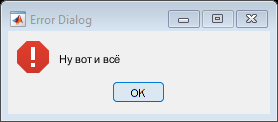

errordlg("Ну вот и всё")

Пример ввода информации:

input('Введите цифру: ')

ans = 1

input('Введите текст: ', 's')

ans = 'еуе'

P1 =  inputdlg({'Первое значение: ', 'Второе значение: '})

P1 = 2×1 cell array
    {'22'}
    {'22'}


list = {'Лебедь', 'Рак', 'Щука'};
listdlg('ListString',list, 'PromptString', 'Укажите направление:')

ans =      1     2     3


## Создание и использование функций

Функция может быть объявлена одним из приведённых способов:

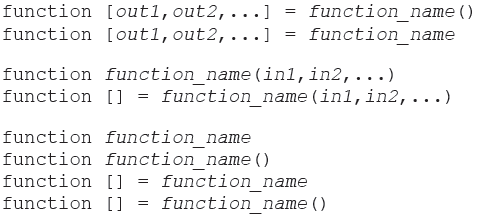

где `out1`, `out2`, ... - выходные параметры, а `in1`, `in2`, ... - входные.

Если функции объявляются в одном файле с программой, использующих их, то их объявление должно быть в конце программы. Например, функция twice (находится в конце этого файла) объявляется так:

Функцию можно вызвать по её названию:

x1 = twice(23)

x1 = 4

Следует заметить, что у функции есть своё пространство переменных (Workspace), которое никак не конфликтует и не пересекается с пространством переменных исполняемой программы:

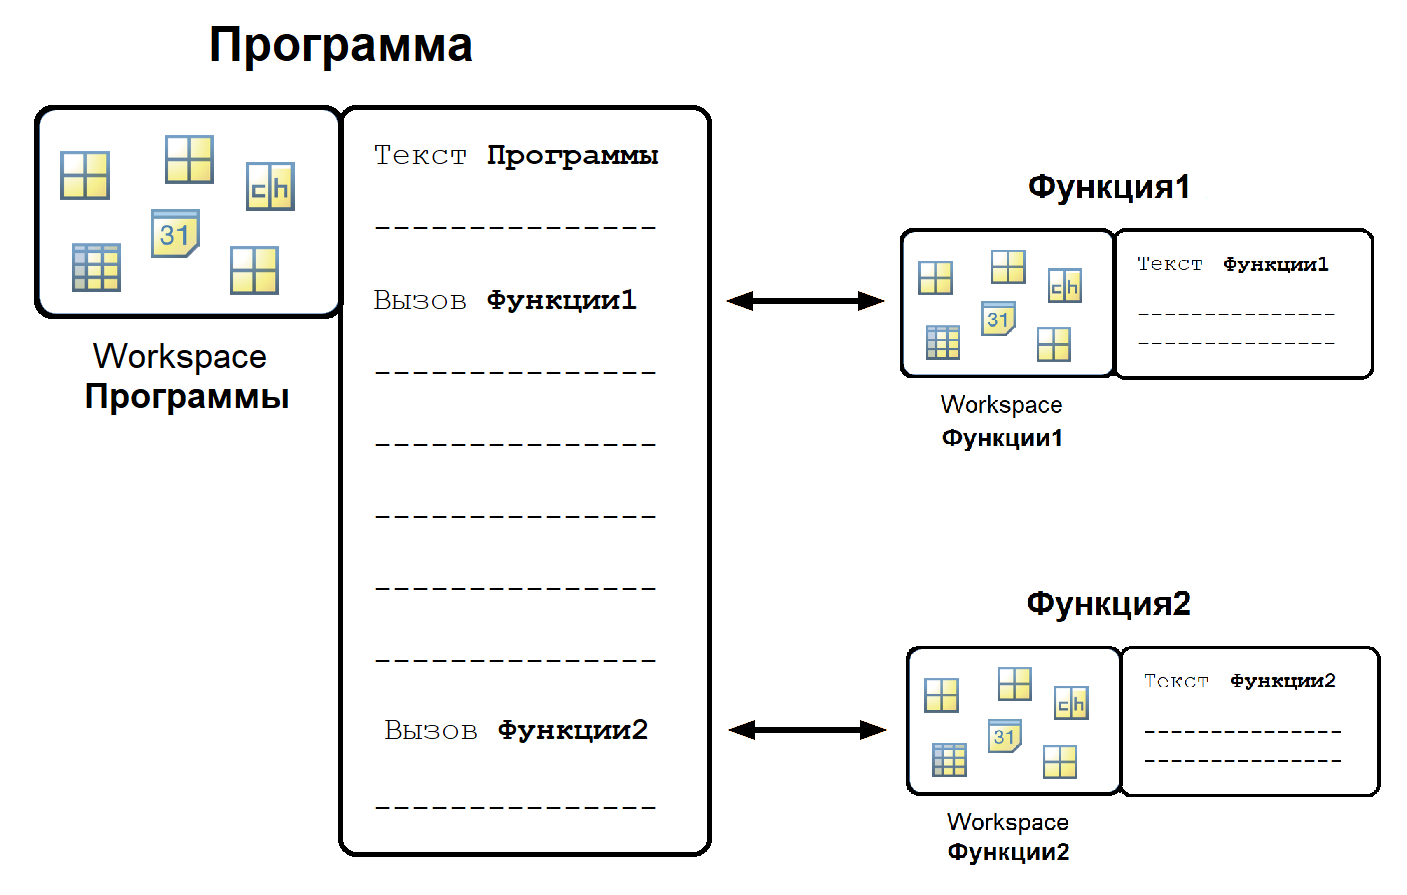

Использованные функции:

function output = twice(input)
    output = input*2;
end